# Examen RA3L "intro Matlab"      9 novembre 2023  12h45 -> 14h15 (1h30) 

% Nom :  Adda                                           /10
% Prénom :      SAB
% Matricule :   

## Loi de Kepler

Copernic avait découvert dans ses recherches que plus une planète était éloignée du Soleil, plus elle mettait du temps à en faire le tour. Kepler a découvert une loi mathématique qui relie la période orbitale (`T`) et le rayon moyen de l'orbite (`R`) :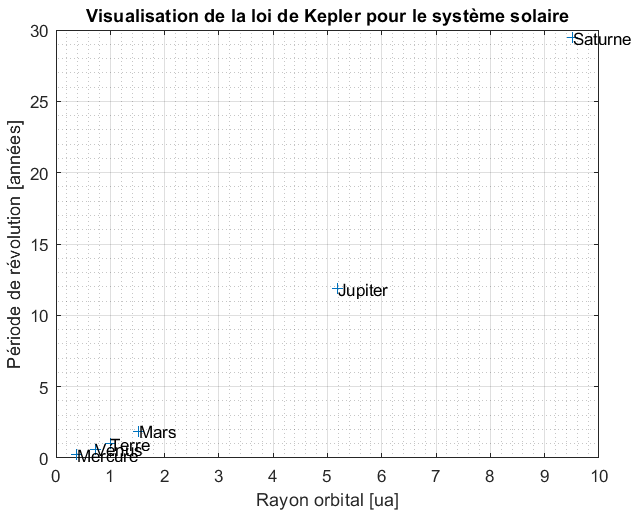

`T²/R³ = constante`

**1) Récupérer les données du fichier "systeme_solaire.mat" fourni.** Ce fichier contient les vecteurs suivants :

- '`T`' (y): période de révolution des planètes autour du Soleil *[en années]*.

- '`R`'(x) : rayon orbital des planètes *[eFn unités astronomiques (ua)];* 1 ua correspond au rayon orbital de la Terre, soit 150 millions de km.

- '`nom`' : nom des planètes (matrice 8 x 7 : chaque ligne correspond à un nom de 7 caractères; les noms courts (ex : Mars) sont complétés par des espaces pour arriver à 7 caractères par ligne)

Afficher les données sous forme d'un graphe présentant la période en fonction du rayon orbital. **Créer un vecteur R2, sans les rayons orbitaux d'Uranus et de Neptune, car les données concernant la période orbitale (**`T`**) manquent.** Aide pour l'affichage des noms des planètes : commande "text".

*(3 points)*

Résultat attendu :

%1.
clear all; close all;clf;
load('systeme_solaire.mat')
clf;

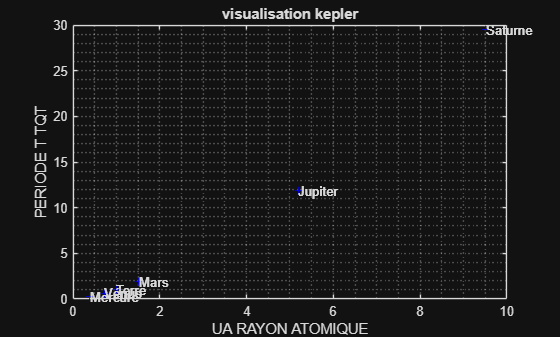

R1=R(1:end-2);

plot(R1,T,'+b')
grid minor
hold on
xlabel('UA RAYON ATOMIQUE')
ylabel('PERIODE T TQT')
title('visualisation kepler')
nom1=nom(1:end-2,:);
text(R1,T,nom1)

2) La relation entre les périodes et les rayons orbitaux des planètes suit la loi de Kepler :

 `T = k * R^(3/2)`.

Ajuster, via Matlab, la valeur de k, de manière à trouver la courbe **qui passe au plus près des points donnés (au sens des moindres carrés).**

*(2 points)*

Résultat attendu : k = 1 à peu près, car pour la Terre, T = 1 an pour R = 1 ua !

%2.
fun1=@(k) k.*R1.^(3/2);
cost1=@(k) norm(fun1(k)-T);
k=0;
min1=fminsearch(cost1,k);


3) Définir un vecteur `R_fit` de 300 valeurs de 0,1 à 30 ua. Calculer les périodes correspondantes :

- `T_fit` via la courbe ajustée à la question précédente ;

- `T_interp` via une interpolation (méthode **pchip**).

A partir de la courbe ajustée, calculer les périodes de( révolution d'Uranus et de Neptune qui manquent dans le vecteur `T` de départ.

Réaliser une figure composée de 2 graphes (voir ci-dessous) :

    Afficher sur le 1er graphe (en fonction du rayon orbital) :

- les données de départ ('+' bleus) ;

- la courbe ajustée (`T_fit`) en rouge ;

- les données recalculées pour Uranus et Neptune ('+' rouges)

- la courbe obtenue par interpolation (`T_interp`) en noir ;

- les points de la courbe interpolée dont l'ordonnée diffère de plus d'un an par rapport à ceux de la courbe ajustée ('o' verts).

    Afficher sur le 2ème graphe (en fonction du rayon orbital) :

- les différences entre les ordonnées des courbes ajustée et interpolée en noir

NB: L'utilisation du symbole "Delta" est un bonus.

*(4 points)*

Résultat attendu :

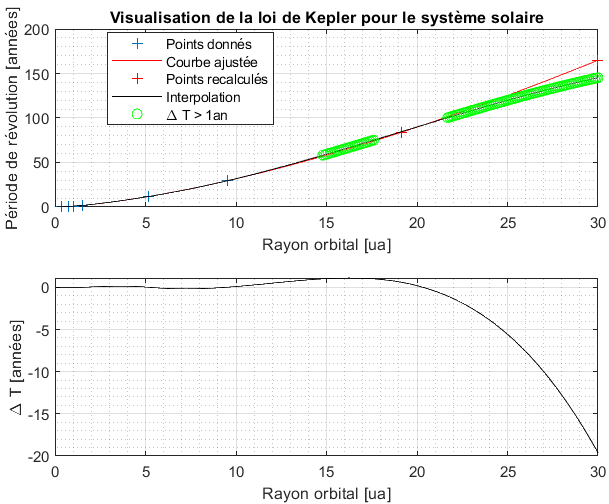

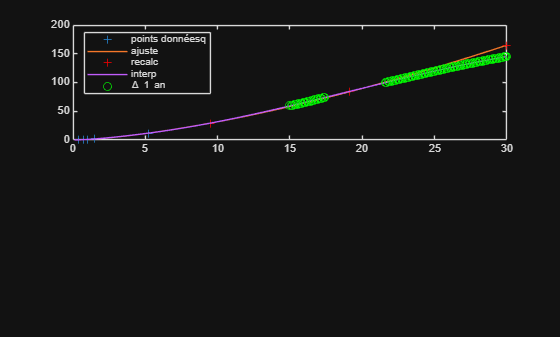

R_fit=linspace(0.1,30,300);
fun2=@(k,R) k.*R.^(3/2);
R3=R(end-2:end);
T_interp=interp1(R1,T,R_fit,'pchip');

d=abs(T_interp-fun2(min1,R_fit));
[a,idx]=find(d>1);
dif=T_interp(idx);
dif1=R_fit(idx);

subplot(2,1,1)
plot(R1,T,'+',R_fit,fun2(min1,R_fit),R3,fun2(min1,R3),'+r',R_fit,T_interp,dif1,dif,'og')
legend('points donnéesq','ajuste','recalc','interp','\Delta 1 an','Location','northwest')

4) Les différences de rayon et de période entre les planètes ne rend pas la lecture aisée avec un graphique conventionnel. Réafficher les données suivantes dans une nouvelle figure dans un graphique bilogarithmique (commande 'loglog')

- les données de départ ('+' bleus) ;

- la courbe ajustée (`T_fit`) en rouge ;

- les données retrouvées pour Uranus et Neptune ('+' rouges) ;

*(1 point)*

Résultat attendu :

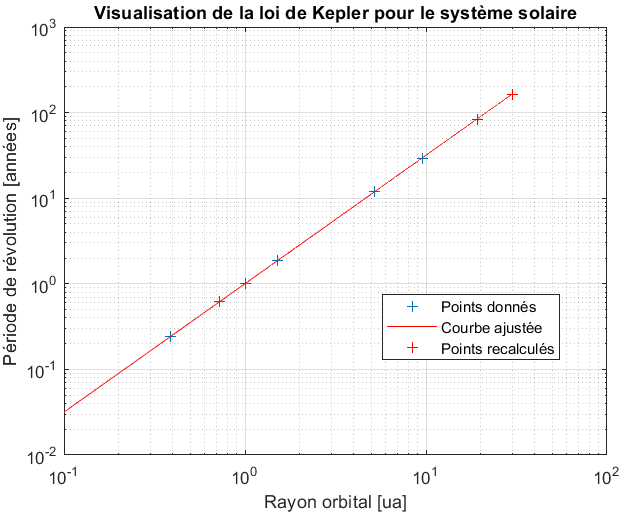

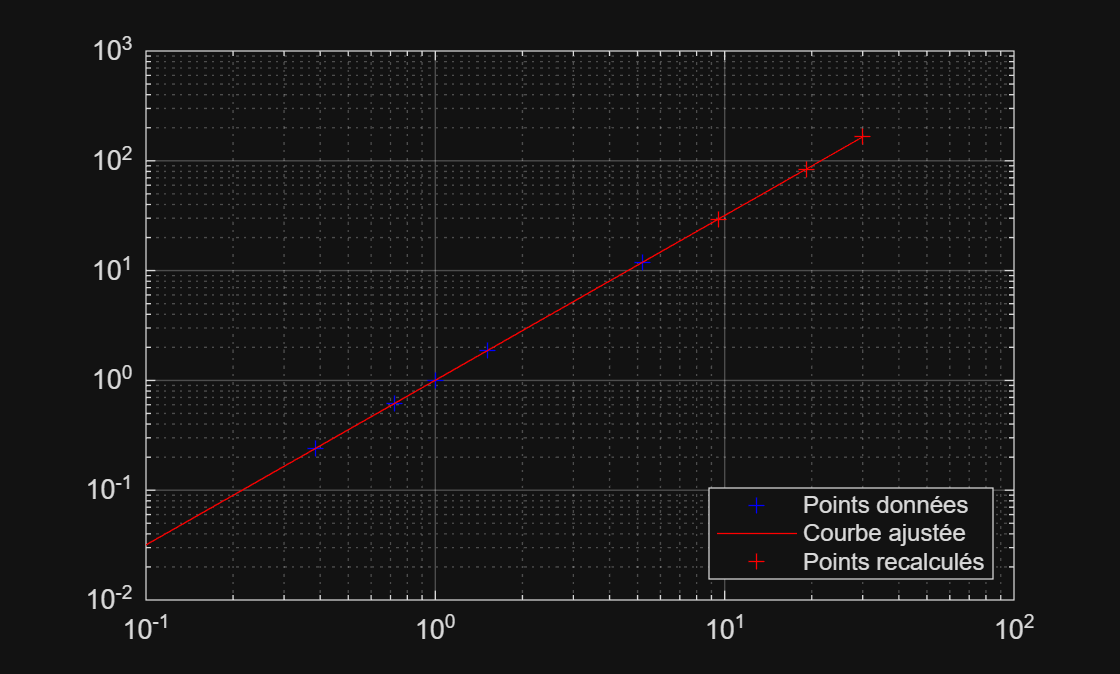

clf;
